nrepeats = 1;
Data = zeros(nrepeats,128);
save 'C:\Users\verasonics\Documents\Vantage-4.8.4-2305101400\Verasonics-Acoustic-Tweezer\Measurements\ProbeImpedanceCheckFull\Data.mat' 'Data'
for n = 1:nrepeats
    save 'C:\Users\verasonics\Documents\Vantage-4.8.4-2305101400\Verasonics-Acoustic-Tweezer\Measurements\ProbeImpedanceCheckFull\n' 'n'
    ProbeZdata = ProbeImpedanceCheck(1.1);
    %disp(ProbeZdata)
    load 'C:\Users\verasonics\Documents\Vantage-4.8.4-2305101400\Verasonics-Acoustic-Tweezer\Measurements\ProbeImpedanceCheckFull\n.mat'
    disp(n)
    data = ProbeZdata.MeasZperCh;
    load 'C:\Users\verasonics\Documents\Vantage-4.8.4-2305101400\Verasonics-Acoustic-Tweezer\Measurements\ProbeImpedanceCheckFull\Data.mat'
    Data(n,:) = data;
    save 'C:\Users\verasonics\Documents\Vantage-4.8.4-2305101400\Verasonics-Acoustic-Tweezer\Measurements\ProbeImpedanceCheckFull\Data.mat' 'Data'
end

     1



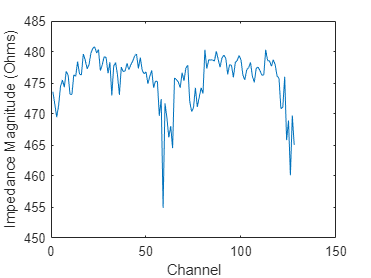

plot(Data')
xlabel('Channel')
ylabel('Impedance Magnitude (Ohms)')

%avrgData = mean(Data,1);
%plot(avrgData)
%xlabel('Channel')
%ylabel('Mean Impedance Magnitude (Ohms)')